Locatie van alle MATLAB functies van Modern Robotics:

**\robotica_labo_student\modernrobotics\packages\MATLAB\mr**

**Voor help, typ in command line voor een zekere <function>:**

**>> help <function>**

**vb. >> help AxisAng3**

Alle functiedocumentatie vind je hier: [**https://github.com/sadegroo/ModernRobotics/blob/master/packages/MATLAB/README.md**](https://github.com/sadegroo/ModernRobotics/blob/master/packages/MATLAB/README.md)

**zie ook \robotica_labo_student\Voorbeelden**

MATLAB-syntax spiekbriefje


% Alles na een %-teken is commentaar en wordt niet uitgevoerd.
% Twee %%-tekens starten een nieuwe sectie in een .m file 
% in .mlx file gebruik je knop LIVE EDITOR > SECTION > Section Break(handig om stukje per stukje te runnen).

%% Haakjes: [ ], ( ), { }
% [ ]  rechte haken  -> matrices en vectoren AANMAKEN (standaard type is
% double
% ( )  ronde haken   -> elementen OPVRAGEN (indexeren) en functies AANROEPEN
% { }  accolades     -> cell arrays (containers voor gemengde datatypes)

v = [1 2 3];          % rijvector: spaties (of komma's) scheiden KOLOMMEN
w = [1; 2; 3];        % kolomvector: puntkomma's scheiden RIJEN
A = [1 2 3; 4 5 6; 7 8 9];   % 3x3-matrix: 3 rijen, gescheiden door ;

c = {1, 'tekst', [1 2 3]};   % cell array: mag verschillende types bevatten
c{2}                          % element opvragen uit een cell array met { }

ans = 'tekst'


%% De puntkomma ; aan het einde van een regel
x = 5;                % MET ;   -> resultaat wordt NIET in het Command Window getoond
y = 6                % ZONDER ; -> resultaat wordt WEL getoond

y = 6

% Binnen [ ] betekent ; dus iets anders: daar start het een nieuwe rij.

%% De dubbelepunt : (colon)
r = 1:5;              % reeks 1, 2, 3, 4, 5 (stapgrootte 1)
r2 = 0:0.5:2;         % reeks 0, 0.5, 1, 1.5, 2 (start:stap:einde)

%% Elementen van matrices adresseren (indexeren start bij 1, niet bij 0!)
A(2,3)                % element op rij 2, kolom 3  -> 6

ans = 6

A(1,:)                % HELE eerste rij   (: betekent "alle kolommen")

ans =      1     2     3


A(:,2)                % HELE tweede kolom (: betekent "alle rijen")

ans =      2
     5
     8


A(2:3, 1:2)           % deelmatrix: rijen 2 t.e.m. 3, kolommen 1 t.e.m. 2

ans =      4     5
     7     8


A(end, end)           % 'end' = laatste index -> element rechtsonder (9)

ans = 9

A(1,2) = 99;          % element overschrijven

%% Transponeren met '
w2 = v';              % van rijvector een kolomvector maken (en omgekeerd)
At = A';              % matrix transponeren: rijen worden kolommen
% Let op: ' is de complex-geconjugeerde transpose; voor reële getallen
% maakt dat niets uit. De "gewone" transpose is .' of transpose(A).

%% Essentiële vectorfuncties (belangrijk voor robotica!)
a = [1 0 0];
b = [0 1 0];
d = dot(a, b);        % inwendig (scalair) product -> 0 (loodrechte vectoren)
n = cross(a, b);      % kruisproduct -> [0 0 1] (staat loodrecht op a en b)
l = norm(a);          % lengte (norm) van de vector -> 1

%% Matrixbewerkingen en inverse
B = [2 0; 0 4];
Binv = inv(B);        % inverse van een matrix
I = B * Binv;         % matrixproduct -> eenheidsmatrix
% Om een stelsel B*x = b op te lossen is x = B\b beter (sneller en nauwkeuriger)
% dan x = inv(B)*b.
b2 = [4; 8];
xOpl = B \ b2;        % "backslash": lost B*x = b2 op

% Element-per-element bewerkingen: zet een PUNT voor de operator
E = B .* B;           % elementsgewijs vermenigvuldigen (niet matrixproduct!)
F = v .^ 2;           % elk element kwadrateren

%% if / elseif / else
t = 7;
if t > 10
  disp('t is groter dan 10')     % disp toont tekst in het Command Window
elseif t > 5
  disp('t ligt tussen 5 en 10')
else
  disp('t is 5 of kleiner')
end                    % elk blok wordt afgesloten met 'end'

t ligt tussen 5 en 10



%% for-lus (vast aantal herhalingen)
som = 0;
for i = 1:5            % i doorloopt achtereenvolgens 1, 2, 3, 4, 5
  som = som + i;
end
fprintf('De som is %d\n', som);    % geformatteerde uitvoer (%d = geheel getal)

De som is 15



%% while-lus (herhalen zolang een voorwaarde waar is)
teller = 1;
while teller < 100
  teller = teller * 2;   % verdubbel tot we 100 of meer bereiken
end

%% switch (keuze uit meerdere gevallen)
richting = 'links';
switch richting
  case 'links'
      disp('We draaien naar links')
  case 'rechts'
      disp('We draaien naar rechts')
  otherwise              % 'otherwise' vangt alle andere gevallen op
      disp('Onbekende richting')
end

We draaien naar links



%% Plotten
close all % alle figuren sluiten
figure; % niewe figuur maken
plotFrame (eye(3)*0.667,zeros(3,1)); % een kleiner wereldassenstelsel plotten

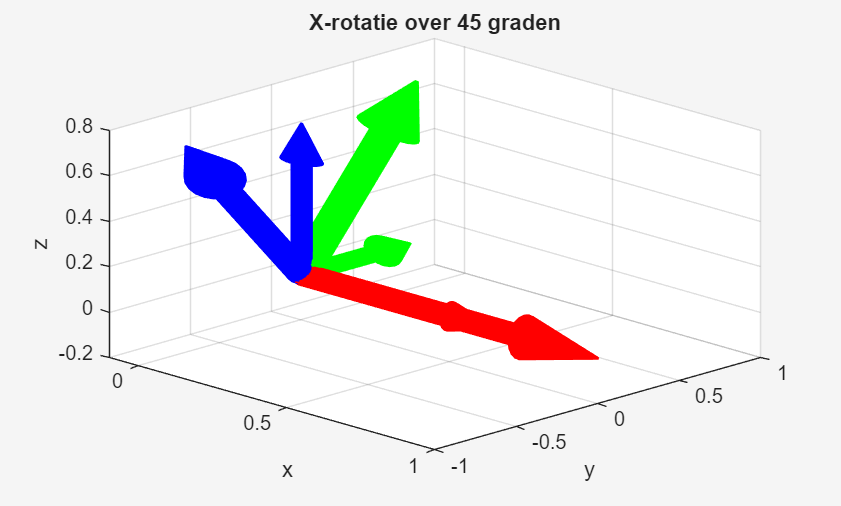

hold on % zorgen dat volgende plot op zelfde figuur gebeurt
plotFrame (RotMatXaxis(pi/4,0),zeros(3,1));  % een geroteerd assenstelsel plotten
hold off

% Eigenschappen figuur aanpassen
fig=gcf; % huidige figuurhandle
fig.Visible = 'On';
fig.CurrentAxes.View = [45 30];
fig.Name = 'X-rotatie over 45 graden';
title('X-rotatie over 45 graden')

MATLAB symbolic spiekbriefje

% Symbolische variabelen aanmaken
syms x y theta            % maakt x, y en theta aan als symbolische variabelen

% Symbolische expressies bouwen (gewoon rekenen met sym-variabelen)
uitdr = sin(theta)^2 + cos(theta)^2 + x^2 + 2*x*y + y^2;

% Vereenvoudigen
v = simplify(uitdr)       % -> x^2 + 2*x*y + y^2 + 1

$$v = x^{2}+2\,x\,y+y^{2}+1$$


% Factoriseren (ontbinden in factoren)
f = factor(x^2 + 2*x*y + y^2)   % -> [x + y, x + y]

$$f = \left(\begin{array}{cc} x+y & x+y \end{array}\right)$$


% Symbolische expressie omzetten naar een gewone MATLAB-functie
% zodat je ze met NUMERIEKE waarden kan aanroepen (snel!)
fh = matlabFunction(v)    % -> function handle: @(x,y) x.^2 + 2.*x.*y + y.^2 + 1

fh = function_handle with value:
    @(x,y)x.*y.*2.0+x.^2+y.^2+1.0


fh(1, 2)                  % aanroepen met gewone getallen -> 10

ans = 10


% Tip: leg de volgorde van de argumenten zelf vast met 'Vars',
% anders kiest MATLAB ze alfabetisch:
fh2 = matlabFunction(v, 'Vars', [y x]);   % nu is de volgorde (y, x)